5.  Use 2D Finite Differences to solve the following BVP

$u_{\mathrm{xx}} +u_{\mathrm{yy}} +2u=0$,    $0<x<1$,$0<y<1$

subject to the boundary condition $u\left(x,y\right)=\mathrm{sin}\left(\left(x+y\right)\pi \right)$on the boundary. Use 6 grid points(4 interior points) in each of the x and y direction. Code up your FD method in to Matlab and plot the solution, test how your solution changes with grid size.

With Finite Differences Method


$$\begin{array}{l}
\frac{1}{h^2 }\left(u_{i,j+1} -2u_{i,j} +u_{i,j-1} \right)+\frac{1}{h^2 }\left(u_{i+1,j} -2u_{i,j} +u_{i+1,j} \right)-2u_{i,j} =0\\
\frac{1}{h^2 }\left(u_{i,j+1} -4u_{i,j} +u_{i,j-1} {+u}_{i+1,j} +u_{i+1,j} \right)-2u_{i,j} =0\\
\frac{u_{i,j+1} }{h^2 }-\frac{4u_{i,j} }{h^2 }+\frac{u_{i,j-1} }{h^2 }+\frac{u_{i+1,j} }{h^2 }+\frac{u_{i+1,j} }{h^2 }-\frac{2h^2 u_{i,j} }{h^2 }=0\\
\frac{u_{i,j+1} }{h^2 }+\frac{u_{i,j-1} }{h^2 }+\frac{u_{i+1,j} }{h^2 }+\frac{u_{i+1,j} }{h^2 }-\left(\frac{4u_{i,j} }{h^2 }+\frac{2h^2 u_{i,j} }{h^2 }\right)=0\\
\frac{u_{i,j+1} }{h^2 }+\frac{u_{i,j-1} }{h^2 }+\frac{u_{i+1,j} }{h^2 }+\frac{u_{i+1,j} }{h^2 }-u_{i,j} \left(\frac{4}{h^2 }+2\right)=0\\
u_{i,j+1} +u_{i,j-1} +u_{i+1,j} +u_{i+1,j} =u_{i,j} \left(4+2h^2 \right)\\
\frac{1}{4+2h^2 }\left(u_{i,j+1} +u_{i,j-1} +u_{i+1,j} +u_{i+1,j} \right)=u_{i,j} 
\end{array}$$



$$u_{i,j} =\frac{1}{4+2h^2 }\left(u_{i,j+1} +u_{i,j-1} +u_{i+1,j} +u_{i+1,j} \right)$$


So compare to the last question the only thing changed is the coefficient of $u_{i,j}$

Therefore we will use the same mathod to generate the matrix V and b.

The only change in the method is:

We will set $k=\left\lbrack \begin{array}{ccc}
0 & -1 & 0\\
-1 & 4+2h^2  & -1\\
0 & -1 & 0
\end{array}\right\rbrack$        (11)

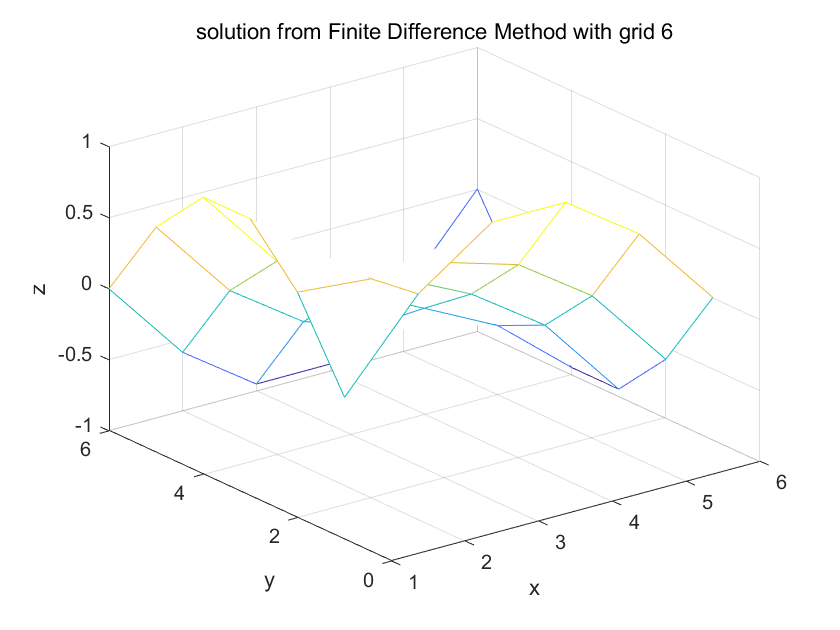

clear
%set number of grid=6
nx = 6;
ny = 6;

u = zeros(nx, ny);
x = linspace(0, 1, nx);
y = linspace(0, 1, ny);
%set the initial boundary condition
u(nx, :) = sin(pi*(x + 1));
u(:, ny) = sin(pi*(1 + y));
u(1, :) = sin(pi*(x + 0));
u(:, 1) = sin(pi*(0 + y));
u = flipud(u);

[uk] = FD(nx, ny, u);
%plot
mesh(uk)
title("solution from Finite Difference Method with grid 6")
xlabel('x')
ylabel('y')
zlabel('z')

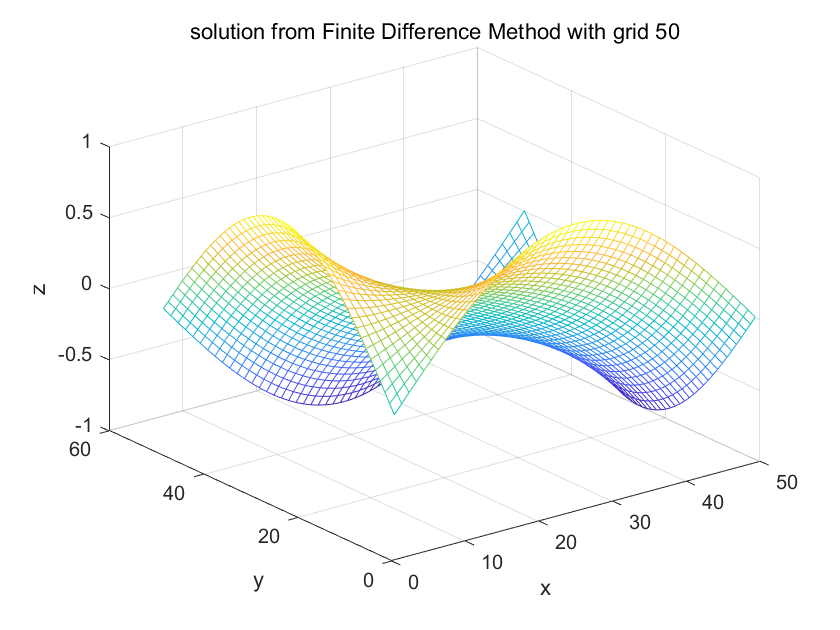


%test for larger grid point
nx50 = 50;
ny50 = 50;

u50 = zeros(nx50, ny50);
x50 = linspace(0, 1, nx50);
y50 = linspace(0, 1, ny50);
%set the initial boundary condition
u50(nx50, :) = sin(pi*(x50 + 1));
u50(:, ny50) = sin(pi*(1 + y50));
u50(1, :) = sin(pi*(x50 + 0));
u50(:, 1) = sin(pi*(0 + y50));
u50 = flipud(u50);

[uk50] = FD(nx50, ny50, u50);

mesh(uk50)
title("solution from Finite Difference Method with grid 50")
xlabel('x')
ylabel('y')
zlabel('z')

As result the solution will get smooth if we use more grid point.

function [uk] = FD(nx, ny, u)
%function of Finite Different
    h = 1/(nx - 1);%calculate h
    %adjust k with equation (11)
    k=[0 -1 0;
        -1 4 + 2*h^2 -1;
        0 -1 0];
    V = [];
    b = [];
    for j = 2:ny - 1
        for l = 2:nx - 1
            ut = zeros(ny, nx);
            ut(j - 1:j + 1,l - 1:l + 1) = k;
            uc = ut(2:nx - 1, 2:ny - 1);
            V = [V;reshape(uc', 1, (nx - 2)*(ny - 2))];
            b = [b;u(j + 1, l) + u(j, l - 1) + u(j - 1, l) + u(j, l + 1)];
        end
    end
    uin = V\b;
    u(2:nx - 1, 2:ny - 1) = reshape(uin, (nx - 2), (ny - 2))';
    uk = flipud(u);
end